# Optimization

clc;
clear;
close all;

[param, weather, route, driver] = loadData();

effLoss = load("inefficiency.mat").effLoss;
tempCF = load("temperatureCF.mat").tempCF;
velSafe = load("optimalMeanVelocity.mat").velMeanOpt_unitedStops;

cd("C:\Users\giaco\Git_Repositories\Bachelor_Arbeit\Codes\Optimization");

interestDay = datetime(2020,10,20);
enhanceFactor = 1.8;
raceDays = 5;
plotIsRequested = false;
weatherSim = weatherSimFullRace(interestDay, enhanceFactor, raceDays, plotIsRequested);

Colours for plots

colour = struct();
colour.loss = 'r';
colour.solar = 'g';
colour.battery = 'magenta';

#### Cumulative solar energy

EcumSolar = cumtrapz(weatherSim.irradiance.GtotalSec) * param.pv.area * param.pv.eff * tempCF * param.pv.loss.total; %J

#### Battery initial energy and safe to spend energy

SoCend = 0.1;
Ebatmax = param.battery.Emax; %J
EbatSafe = Ebatmax * (1 - SoCend); %J

#### Energy loss

Froll = param.constants.roll; %N
Faero = param.constants.aero * (driver.finishLocDist ./ weatherSim.irradiance.timeSec).^2; %N

Eloss = driver.finishLocDist / effLoss * (Froll + Faero); %J

### Plot

#### Energy, irradiance vs simulation time

% title = 'Uncut plot';
% synchronizeXAxes = true;
% xaxis = weatherSim.irradiance.timeSec;
% xlimVec = [0 xaxis(end)];
% ylimVec = [0, J2kWh(EcumSolar(end)+EbatSafe)];
% builder = VerticalPlotBuilder(synchronizeXAxes, title);
% 
% builder.addPlot(xaxis, weatherSim.irradiance.GtotalSec,'-','Color',colour.solar);
% builder.addPlot(xaxis, weatherSim.irradiance.driving_8_17_Sec * 1000,'-','Color','k');
% builder.addLines('vertical', 32400, 'r');
% builder.addLines('vertical', 48960, 'b');
% builder.setYlabel("Irradiance [Wm^{-2}]");
% builder.setXlim(xlimVec)
% 
% builder.startNewSubplot();
% builder.addPlot(xaxis, J2kWh(EcumSolar),'-','Color',colour.solar);
% builder.addPlot(xaxis, J2kWh(EcumSolar + EbatSafe),'-','Color','b');
% builder.addPlot(xaxis, J2kWh(Eloss),'-','Color',colour.loss);
% builder.setYlabel("Energy [kWh]")
% builder.setLegend("Solar energy","Total budget energy","Energy loss")
% builder.setXlim(xlimVec)
% builder.setYlim(ylimVec)
% 
% builder.setXlabel("Simulation time [s]");
% builder.drawNow()

## Cut only driving time

horizon_8_17 = logical(weatherSim.irradiance.driving_8_17_Sec); %conversion to logical
time_8_17 = weatherSim.irradiance.timeSec(horizon_8_17);

timeLen_8_17 = length(time_8_17);
timeCutSec = linspace(1, timeLen_8_17, timeLen_8_17)';

#### Cumulative energy

EcumSolarCut = EcumSolar(horizon_8_17);
EbudgetTot = EcumSolarCut + EbatSafe;

#### Energy loss cut

FaeroCut = param.constants.aero * (driver.finishLocDist ./ timeCutSec).^2;

ElossCut = driver.finishLocDist / effLoss * (Froll + FaeroCut);

#### Find optimal point

timeOptCut = find(ElossCut <= EbudgetTot, 1, 'first');
fprintf('Optimal driving time: %3.2f h', timeOptCut / 3600)

Optimal driving time: 31.07 h


%adding night duration
time_nonDriving = weatherSim.irradiance.timeSec(~horizon_8_17);
numNights = floor(timeOptCut/(3600 * 9)); %NOW WRONG WITH FIRST DAY STARTS AT 10:00

startNights = find(diff(horizon_8_17) == -1, numNights, 'first') - 1; %check again first and last point
endNights = find(diff(horizon_8_17) == 1, numNights, 'first');

durationSecNights = endNights - startNights;
durationHnights = durationSecNights / 3600;
totNights = sum(durationHnights);

fprintf('Total time: %3.2f h', timeOptCut / 3600 + totNights)

Total time: 44.91 h


velMeanOpt = driver.finishLocDist / timeOptCut;
fprintf('Optimal velocity: %3.2f km/h', velMeanOpt * 3.6)

Optimal velocity: 97.42 km/h

% disp(['Optimal velocity: ', char(string(velMeanOpt * 3.6)), ' km/h'])

### Plot

#### Energy, irradiance vs driving time

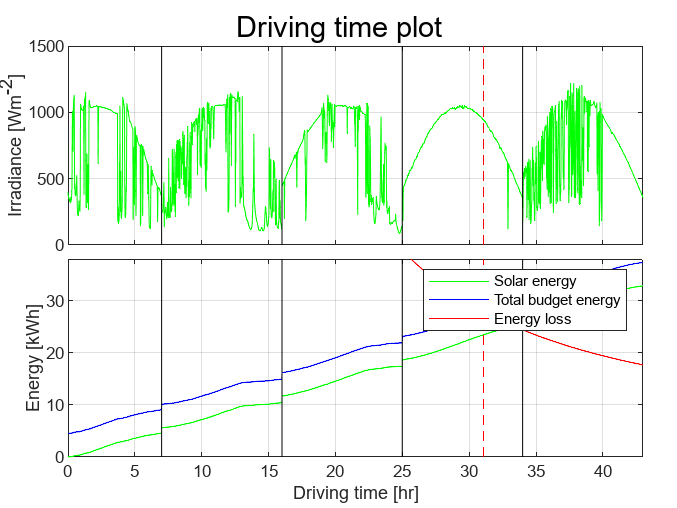

title = 'Driving time plot';
synchronizeXAxes = true;
xaxis = timeCutSec / 3600;
yline17 = (7 : 9 : 9*(raceDays-1))';
xlimVec = [0, xaxis(end)];
ylimVec = [0, J2kWh(EcumSolar(end)+EbatSafe)];
builder = VerticalPlotBuilder(synchronizeXAxes, title);

builder.addPlot(xaxis, weatherSim.irradiance.GtotalSec(horizon_8_17),'-','Color',colour.solar);
builder.addLines('vertical', yline17, 'k');
builder.addLines('vertical', timeOptCut / 3600, 'r--');
builder.setYlabel("Irradiance [Wm^{-2}]");
builder.setXlim(xlimVec)

builder.startNewSubplot();
builder.addPlot(xaxis, J2kWh(EcumSolarCut),'-','Color',colour.solar);
builder.addPlot(xaxis, J2kWh(EbudgetTot),'-','Color','b');
builder.addPlot(xaxis, J2kWh(ElossCut),'-','Color',colour.loss);
builder.addPlot(timeOptCut / 3600, J2kWh(ElossCut(timeOptCut)), 'r.', 'MarkerSize', 20)
builder.addLines('vertical', yline17, 'k');
builder.addLines('vertical', timeOptCut / 3600, 'r--');
builder.setYlabel("Energy [kWh]")
builder.setLegend("Solar energy","Total budget energy","Energy loss")
builder.setXlim(xlimVec)
builder.setYlim(ylimVec)

builder.setXlabel("Driving time [hr]");
builder.drawNow()

## Distance Analysis

distVec = timeCutSec * velMeanOpt;

#### Potential energy

altiInterp = interp1(route.dist, route.alti, distVec);
% EpotDist = param.structure.mass.total * getPhysicalConstants().g * route.alti; %J
EpotDist = param.structure.mass.total * getPhysicalConstants().g * altiInterp; %J

#### Energy loss

FaeroDist = param.constants.aero * velMeanOpt^2; %N

ElossDist = distVec / effLoss * (Froll + FaeroDist); %J

#### Solar energy

EcumSolarDist = EcumSolarCut;

#### Battery energy

EBatDist = Ebatmax + EcumSolarDist - EpotDist - ElossDist;

### Plot

#### Energy vs distance

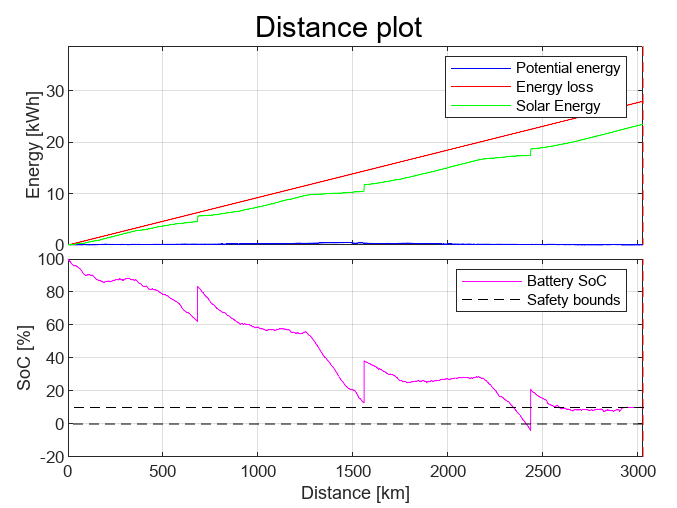

title = 'Distance plot';
synchronizeXAxes = true;
xaxis = distVec / 1000;
xlimVec = [0, driver.finishLocDist / 1000];
ylimVec = [0, max(J2kWh(ElossDist))]; %todo
builder = VerticalPlotBuilder(synchronizeXAxes, title);

builder.addPlot(xaxis, J2kWh(EpotDist),'-','Color','b');
builder.addPlot(xaxis, J2kWh(ElossDist),'-','Color',colour.loss);
builder.addPlot(xaxis, J2kWh(EcumSolarDist),'-','Color',colour.solar);
builder.addLines('vertical', driver.finishLocDist / 1000, 'r--');
builder.setYlabel("Energy [kWh]")
builder.setLegend("Potential energy","Energy loss","Solar Energy")
builder.setXlim(xlimVec)
builder.setYlim(ylimVec)

builder.startNewSubplot();
builder.addPlot(xaxis, EBatDist / Ebatmax * 100,'-','Color',colour.battery);
builder.addLines('horizontal', 0, 'k--');
builder.addLines('vertical', driver.finishLocDist / 1000, 'r--');
builder.addLines('horizontal', (1 - EbatSafe / Ebatmax) * 100, 'k--');
builder.setYlabel("SoC [%]")
builder.setLegend("Battery SoC","Safety bounds")
builder.setXlim(xlimVec)

builder.setXlabel("Distance [km]");
builder.drawNow()

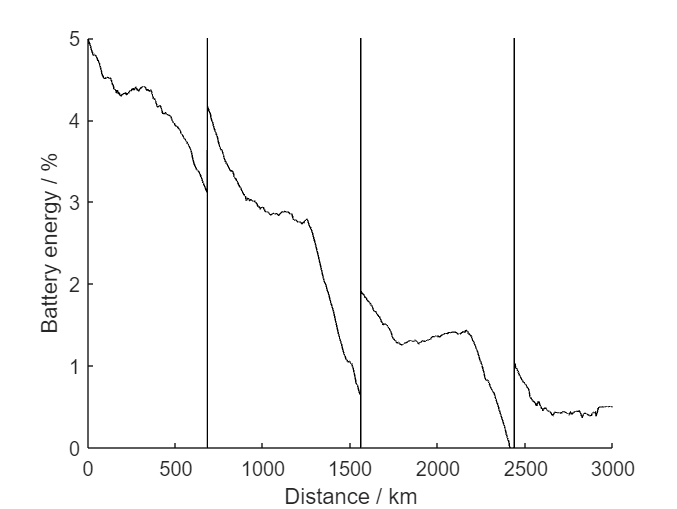

savePlots = false;
step = 8;

figure
hold on
plot(xaxis(1:step:end), J2kWh(EBatDist(1:step:end)), 'k');
plotLines(gca, 'vertical', yline17 * 3.6 * velMeanOpt , 'k')
ylabel("Battery energy / %")
xlabel("Distance / km")
xlim([0, 3000])
ylim([0, J2kWh(Ebatmax)])


if savePlots
    figureName = 'EbatStrategy';
    latexMatlabPlotSaver(figureName, 'cleanFigure', true)
end % if